c1  = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones1\control.dat') ;
t11 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones1\tita1.dat');
t21 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones1\tita2.dat');
ts1 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones1\ts.dat');

c2  = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones2\control.dat'); 
t12 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones2\tita1.dat');
t22 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones2\tita2.dat');
ts2 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones2\ts.dat');

c3  = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones3\control.dat'); 
t13 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones3\tita1.dat');
t23 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones3\tita2.dat');
ts3 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones3\ts.dat');

c4  = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones4\control.dat'); 
t14 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones4\tita1.dat');
t24 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones4\tita2.dat');
ts4 = load('C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\mediciones4\ts.dat');

% fvtool(t11)

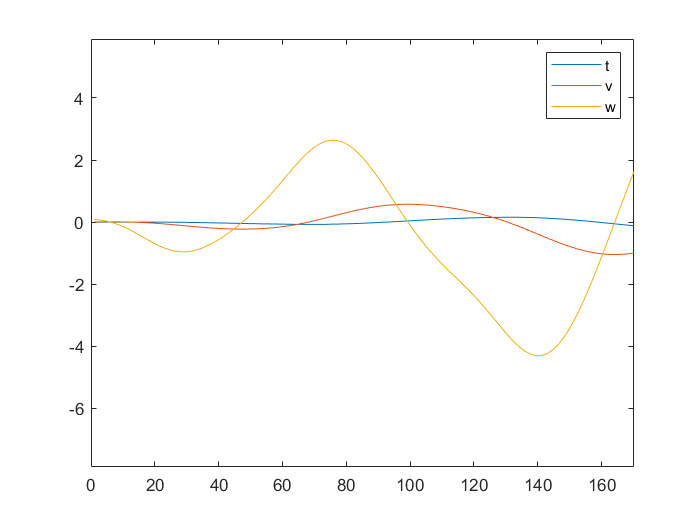

%  N = 4;
% [b, a] = butter(N, 0.05, 'low'); % design Butterworth filter
% % fvtool(b,a)
%     
% 
% t11 = filtfilt(b, a, t11); %filtfilt filtra con el modulo al cuad por lo que 
%                            % no genera un desfasaje
% t21 = filtfilt(b, a, t21);
% t12 = filtfilt(b, a, t12);
% t22 = filtfilt(b, a, t22);
% t13 = filtfilt(b, a, t13);
% t23 = filtfilt(b, a, t23);
% t14 = filtfilt(b, a, t14);
% t24 = filtfilt(b, a, t24);
% 
% plot(t22)

[v11 , w11] = centradas(t11(:,1), ts1);
[v21 , w21] = centradas(t21(:,1), ts1);
ts1 = ts1(3:length(ts1)-2)';
c1 = c1(3:length(c1)-2);
t11 = t11(3:length(t11)-2);
v11 = v11(2:length(v11)-1);
t21 = t21(3:length(t21)-2);
v21 = v21(2:length(v21)-1);

hold off
plot(t11)
hold on
plot(v11)
hold on
plot(w11)
legend('t','v','w')
hold off

hold off

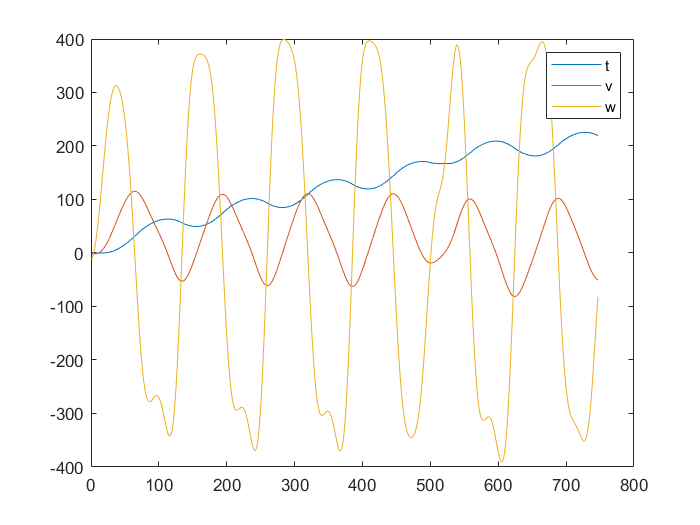

plot(t21)
hold on
plot(v21)
hold on
plot(w21)
legend('t','v','w')
hold off


[v12 , w12] = centradas(t12(:,1), ts2);
[v22 , w22] = centradas(t22(:,1), ts2);
ts2 = ts2(3:length(ts2)-2)';
c2 = c2(3:length(c2)-2);
t12 = t12(3:length(t12)-2);
v12 = v12(2:length(v12)-1);
t22 = t22(3:length(t22)-2);
v22 = v22(2:length(v22)-1);

hold off

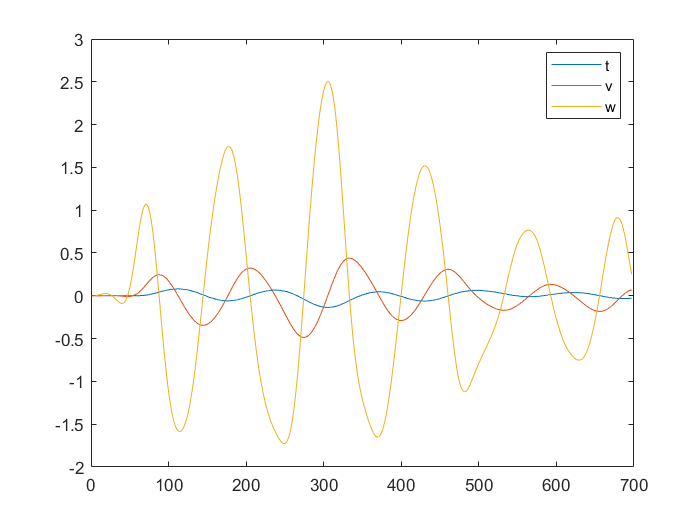

plot(t12)
hold on
plot(v12)
hold on
plot(w12)
legend('t','v','w')
hold off

hold off

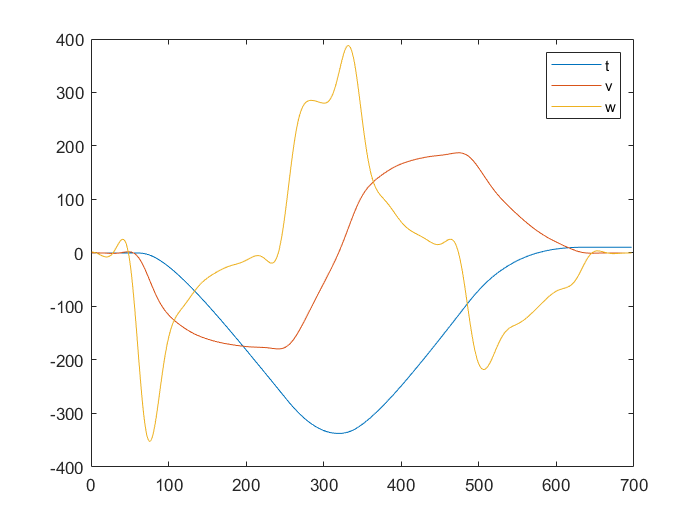

plot(t22)
hold on
plot(v22)
hold on
plot(w22)
legend('t','v','w')
hold off

% plot(t23)
% hold on

[v13 , w13] = centradas(t13(:,1), ts3);
[v23 , w23] = centradas(t23(:,1), ts3);
ts3 = ts3(3:length(ts3)-2)';
c3 = c3(3:length(c3)-2);
t13 = t13(3:length(t13)-2);
v13 = v13(2:length(v13)-1);
t23 = t23(3:length(t23)-2);
v23 = v23(2:length(v23)-1);

hold off

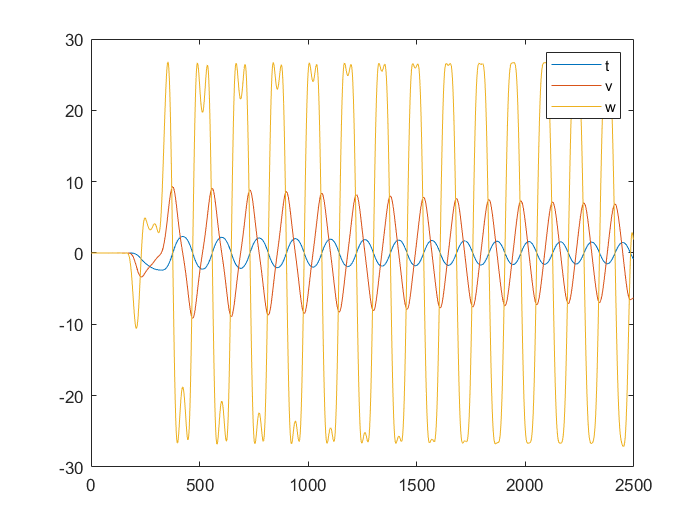

plot(t13)
hold on
plot(v13)
hold on
plot(w13)
legend('t','v','w')
hold off

hold off

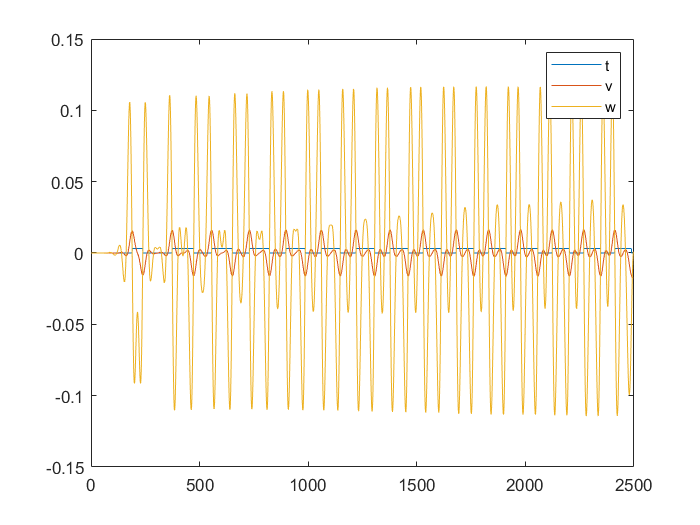

plot(t23)
hold on
plot(v23)
hold on
plot(w23)
legend('t','v','w')
hold off

% plot(t23)
% hold on
% plot(v23)
% hold on
% plot(w23)
% legend('tc','t','v','w')
% hold off

[v14 , w14] = centradas(t14(:,1), ts4);
[v24 , w24] = centradas(t24(:,1), ts4);
ts4 = ts4(3:length(ts4)-2)';
c4 = c4(3:length(c4)-2);
t14 = t14(3:length(t14)-2);
v14 = v14(2:length(v14)-1);
t24 = t24(3:length(t24)-2);
v24 = v24(2:length(v24)-1);


xc = xcorr(v12,v12)

xc =    -0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0003
   -0.0003
   -0.0003
   -0.0003
   -0.0004


xd = xcorr(w12,v12)

xd =    -0.0004
   -0.0008
   -0.0010
   -0.0012
   -0.0012
   -0.0010
   -0.0008
   -0.0003
    0.0003
    0.0010



[m, tm] = max(abs(xc))

m = 30.1309

tm = 697

[mC, tC] = max(abs(xd))

mC = 142.6674

tC = 728


save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 1'\velocidad1.dat v11 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 1'\velocidad2.dat v21 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 1'\tita1.dat t11 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 1'\tita2.dat t21 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 1'\aceleración1.dat w11 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 1'\aceleración2.dat w21 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 1'\control.dat c1 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 1'\tiempo.dat ts1 -ascii

save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 2'\velocidad1.dat v12 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 2'\velocidad2.dat v22 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 2'\tita1.dat t12 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 2'\tita2.dat t22 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 2'\aceleración1.dat w12 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 2'\aceleración2.dat w22 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 2'\control.dat c2 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 2'\tiempo.dat ts2 -ascii

save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 3'\velocidad1.dat v13 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 3'\velocidad2.dat v23 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 3'\tita1.dat t13 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 3'\tita2.dat t23 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 3'\aceleración1.dat w13 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 3'\aceleración2.dat w23 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 3'\control.dat c3 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 3'\tiempo.dat ts3 -ascii

save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 4'\velocidad1.dat v14 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 4'\velocidad2.dat v24 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 4'\tita1.dat t14 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 4'\tita2.dat t24 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 4'\aceleración1.dat w14 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 4'\aceleración2.dat w24 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 4'\control.dat c4 -ascii
save C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2\Resultados\'mediciones 4'\tiempo.dat ts4 -ascii

function [v , w] = centradas(tit,ts)
    T =  ts(1,3)-ts(1,2 );
    n = length(tit);
    
    for i=2:n-1
        vaux(i-1,1) = ( tit(i+1)-tit(i-1) )/(2*T);
    end
    N = 4;
    [b, a] = butter(N, 0.05, 'low'); % design Butterworth filter
    v = filtfilt(b, a, vaux); % apply filter to data
    
    n = length(v);
    for i=2:n-1
        w(i-1,1) = ( v(i+1)-v(i-1) )/(2*T);
    end
end

%%
